# Full Wave Simulator

Converts LTSPICE .txt files to a MATLAB Matrix and plots

## Directory and Internal Libraries/Functions

Sets paths easily to run, calling functions that import different data types

computer = "PC";
if (strcmp(computer, 'PC')) % PC
    %cd 'G:\My Drive\Code\LTSpice\200630 xGAN xGEM Load Responses V0';
    cd 'C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1'
    addpath( 'G:\My Drive\Code\LTSpice\200825 xGAN xGEM Load Responses V1\', ...  % LT Spice output response
        'C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1',...
        'C:\Users\johns\Documents\Github\QEM-MATLAB\Data Converters\LTSpice_Converter', ... % LT Spice reader from Github
        'C:\Users\johns\Documents\Github\QEM-MATLAB', ...    % Access to generic libraries
        'G:\My Drive\Code\COMSOL\xGAN Gated Mirror Sims\Export'); %new comsol stuff
    
elseif (strcmp(computer, 'Mac'))
    %cd 'C:\Users\johns\Documents\Github\QEM-MATLAB\Data Converters\LTSpice_Converter'
    addpath('/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/QEM-MATLAB/Data Converters/LTSpice_Converter', ...
        '/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/QEM-MATLAB', ...
        '/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/Gated-Mirror_xGANxSCAxGEM/200801 xGAN Full Module v1');
end

load('ImpVariables.mat')

## Generate Impedance Response of Load

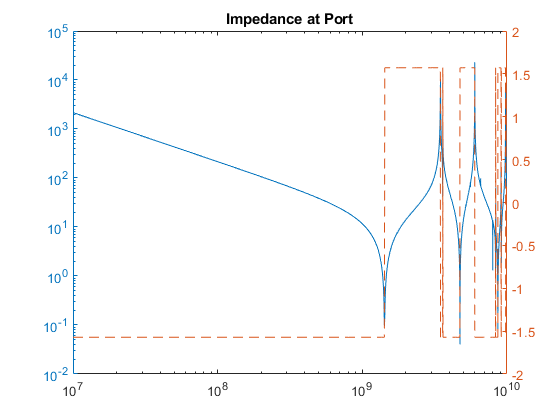

% Workbook for impedance math in "C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1"
% Result is plotted
clf
port = ImportCOMSOL_Z('Kimball_Impedance.txt');
yyaxis left
loglog(port.freq, abs(port.z))
yyaxis right
semilogx(port.freq, unwrap(angle(port.z)),'LineStyle',"--");
title('Impedance at Port')
hold off


ratFitS = rationalfit(port.freq, port.s11);
generateSPICE(ratFitS, 'JWS_TestNetwork_v0.ckt');

## Convert COMSOL Transfer Function 

filename='Kimball_TF.txt';
makeSymmetric = 1;
[rawTF, symTF] = ImportCOMSOL_TF(filename, port.v, makeSymmetric);

clf;
% Look at transfer Function
yyaxis left
loglog(rawTF.freq,abs(rawTF.fieldTF)); ylabel("TF Amplitude");
yyaxis right
semilogx(rawTF.freq, unwrap(angle(rawTF.fieldTF)),'LineStyle',"--"); ylabel("TF Phase (Radians)"); xlabel("Frequency (Hz)");
title("Port Voltage to Field Transfer Function");
hold off

## Time Domain Constant step exporter

Takes data from batch files in LTSpice and exports

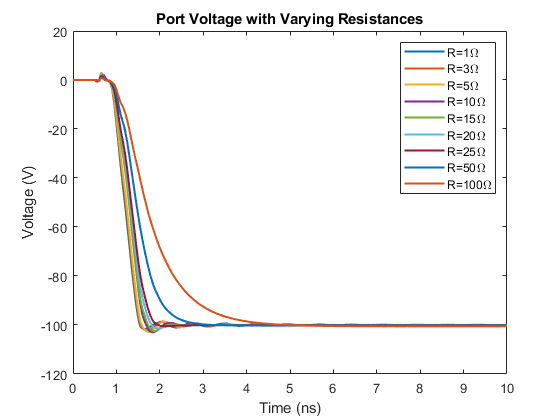

name = '200825 xGAN Kimball Circuit Resetting.txt';
timeRes = 1/20e9; % 20GHz total BW (10Ghz positive)
interpMethod = 'linear'; %pchip linear
[stepR,interpTime, interpVoltAll] = ImportLTSpiceSweep(name, timeRes, interpMethod);

% Plots out result read from file to check
figure()
plot(interpTime/c.nano, interpVoltAll, "LineWidth", 1.5); xlabel('Time (ns)'); ylabel('Voltage (V)'); title('Port Voltage with Varying Resistances')
rNames = string(stepR);
legend('R=' + rNames +'\Omega')
xlim([0 10])

save("200825 xGAN Kimball Circuit Resetting.mat", "stepR", "interpTime", "interpVoltAll");

## Generate and Plot LTSpice Output FT

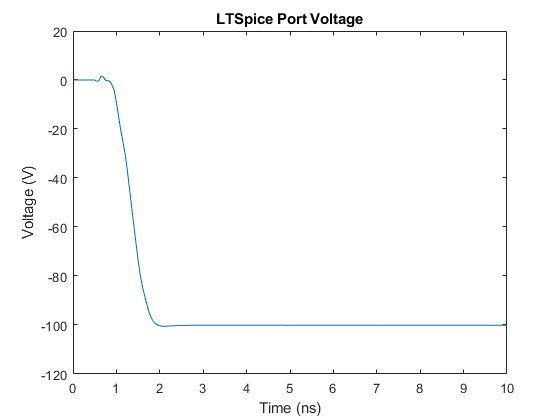

clf;
resIndex = 7;
[time, signal, freq, fftSignal] = inputFunction('Custom', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndex,:));
plot(time/c.nano, signal); xlabel("Time (ns)"); ylabel("Voltage (V)"); title("LTSpice Port Voltage")
xlim([0,10])


%Compares steps
% for resIndexTemp = 1:9
%     [time, signal, freq, fftSignal] = inputFunction('Custom', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndexTemp,:));
%     loglog(freq((end-1)/2+1:end), abs(fftSignal(2:(end+1)/2+1)/abs(fftSignal(1)))); 
%     xlabel("Frequency"); ylabel("Amplitude"); title('Pulse in Frequency Domain')
%     hold on
% end
% xlim([5e8 1e10])
% hold off


## Combine and Plot Output

stepR(resIndex)

ans = 25

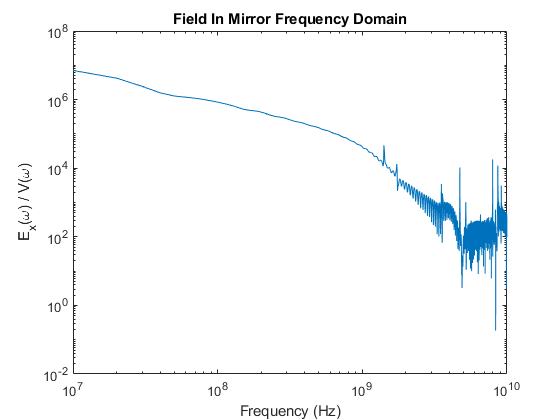

[time, signal, freq, fftSignal] = inputFunction('Custom', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndex,:));

outputFFT = fftSignal.*symTF.fieldTF;
figure()
loglog(freq((end-1)/2+1:end), abs(outputFFT(2:(end+1)/2+1))); title('Field In Mirror Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('E_x(\omega) / V(\omega)')

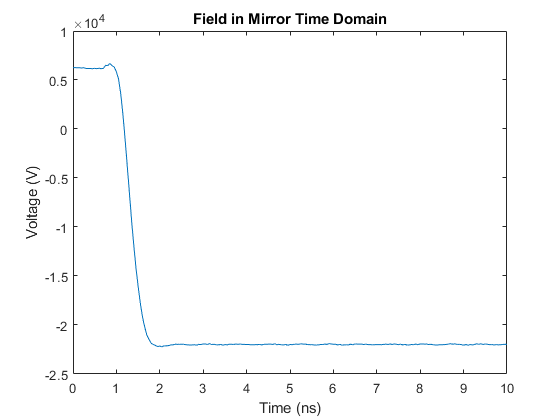


outputSignal = ifft(outputFFT); 
figure()
plot(time/c.nano, outputSignal);
title('Field in Mirror Time Domain'); xlabel("Time (ns)"); ylabel("Voltage (V)");
xlim([0,10])